# Interconnected Systems

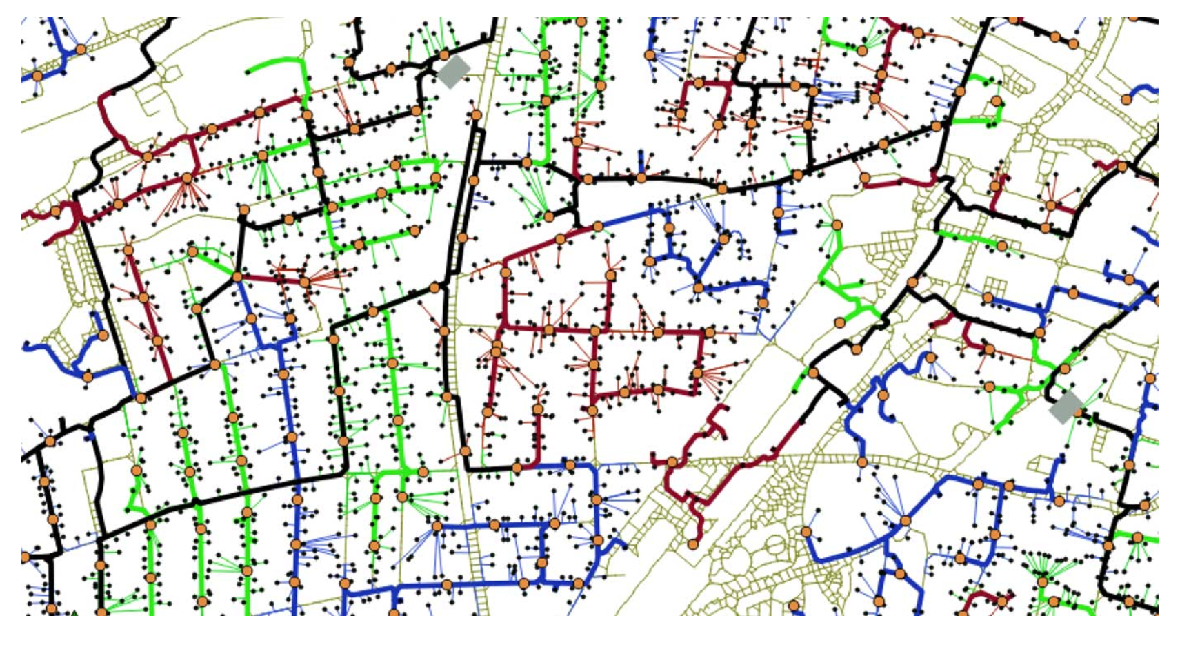

An energy distribution network model (details [here](https://www.nrel.gov/grid/smart-ds.html)).

## Introduction

This live script will describe and analyse some examples of interconnected dynamic LTI systems. Please refer to Part 6 of the course material and the recommended texts for more in-depth theory. 

The online course *MATLAB Onramp* can be used to provide details on simulating interconnected systems in MATLAB.

### Pay Attention

We will only consider examples with factors in common between the numerator and denominator polynomial in the overall transfer function and thus present **hidden dynamics**.

## Example 1: Series Interconnections

### The Hidden Internal Dynamics is Unstable

Consider the system described in the following block diagram:

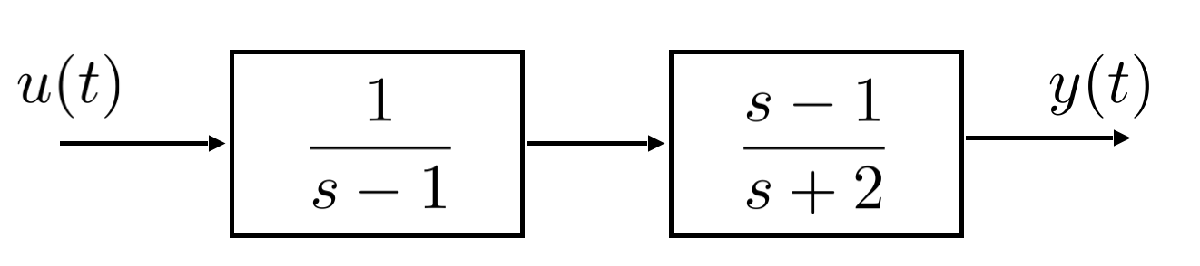


$$G_1(s) = \frac{1}{s-1} \quad G_2(s) =\frac{s-1}{s+2} \qquad G_{tot}(s) = G_1(s) \cdot G_2(s) = \frac{1}{s+2}$$


clear
s = tf('s'); % the transfer function building helper

G1s_series = 1/(s-1); G2s_series = (s-1)/(s+2);

A1 = +1; B1= +1; C1 = 1; D1 = 0;
sysG1 = ss(A1, B1, C1, D1);


G_tot_series = minreal(G1s_series*G2s_series) % let's force the pole/zero simplification -- see 'doc minreal'


G_tot_series =
 
    1
  -----
  s + 2
 
Continuous-time transfer function.
Model Properties


The overall model using state variables is


$$\left\{ \begin{array}{rcl}
\left[ \begin{array}{c} \dot{x}_1(t) \\ \dot{x}_2(t) \end{array} \right] &=& 
\left[ \begin{array}{cc} 1 & 0 \\ 3 & -2 \end{array} \right] \, 
 \left[ \begin{array}{c} x_1(t) \\ x_2(t) \end{array} \right] + 
\left[ \begin{array}{c} 1 \\ 0 \end{array} \right] u(t)\\
y(t) &=& \left[ \begin{array}{cc} 1 & -1 \end{array} \right] \, 
 \left[ \begin{array}{c} x_1(t) \\ x_2(t) \end{array} \right] 
\end{array} \right.$$


Let's define it in MATLAB

A = [1 , 0; 3, -2]; B = [1; 0]; C = [1 , -1]; D = 0; % Refer to Part 6, p.6

sys_TOT_series = ss(A, B, C, D);
tf(sys_TOT_series)


ans =
 
     s - 1
  -----------
  s^2 + s - 2
 
Continuous-time transfer function.
Model Properties


% forcing the simplification
minreal(tf(sys_TOT_series))


ans =
 
    1
  -----
  s + 2
 
Continuous-time transfer function.
Model Properties


#### The Input and the Simulation Settings

Now, let's assign the simulation settings and the system input:


% -----------------------------------------------------------------------
Tstop = 2; % [s] - the simulation starts at the time instant 0 and ends at thee time instant Tstop

% let's define the input time function
% let's generate NT samples for the input signal
NT = 1e4;
t = linspace(0, Tstop, NT);

% the input values
U = 2 + 1.75 .* exp(-2.4.*t) .* cos(2*pi*4.*t); 


#### The Simulation

% --- simulation of G1 ONLY ---
[yG1, ~, xG1] = lsim(G1s_series, U, t);

% --- simulation of G2 ONLY ---
[yG2, ~, xG2] = lsim(G2s_series, yG1, t); % <-- PAY ATTENTION: the output of G1(s) is the input for G2(s)

% --- simulation of the full system ---
[yOut, ~, xOut] = lsim(sys_TOT_series, U, t);
% let us run the model and retrieve the results 


y1 = yG1; % output of the block G1
y2 = yG2; % output of the block G2
y_state = yOut; % output of the state space model

t_stamps = t; 
% time instants corresponding to the solution samples 

#### The Simulation Results

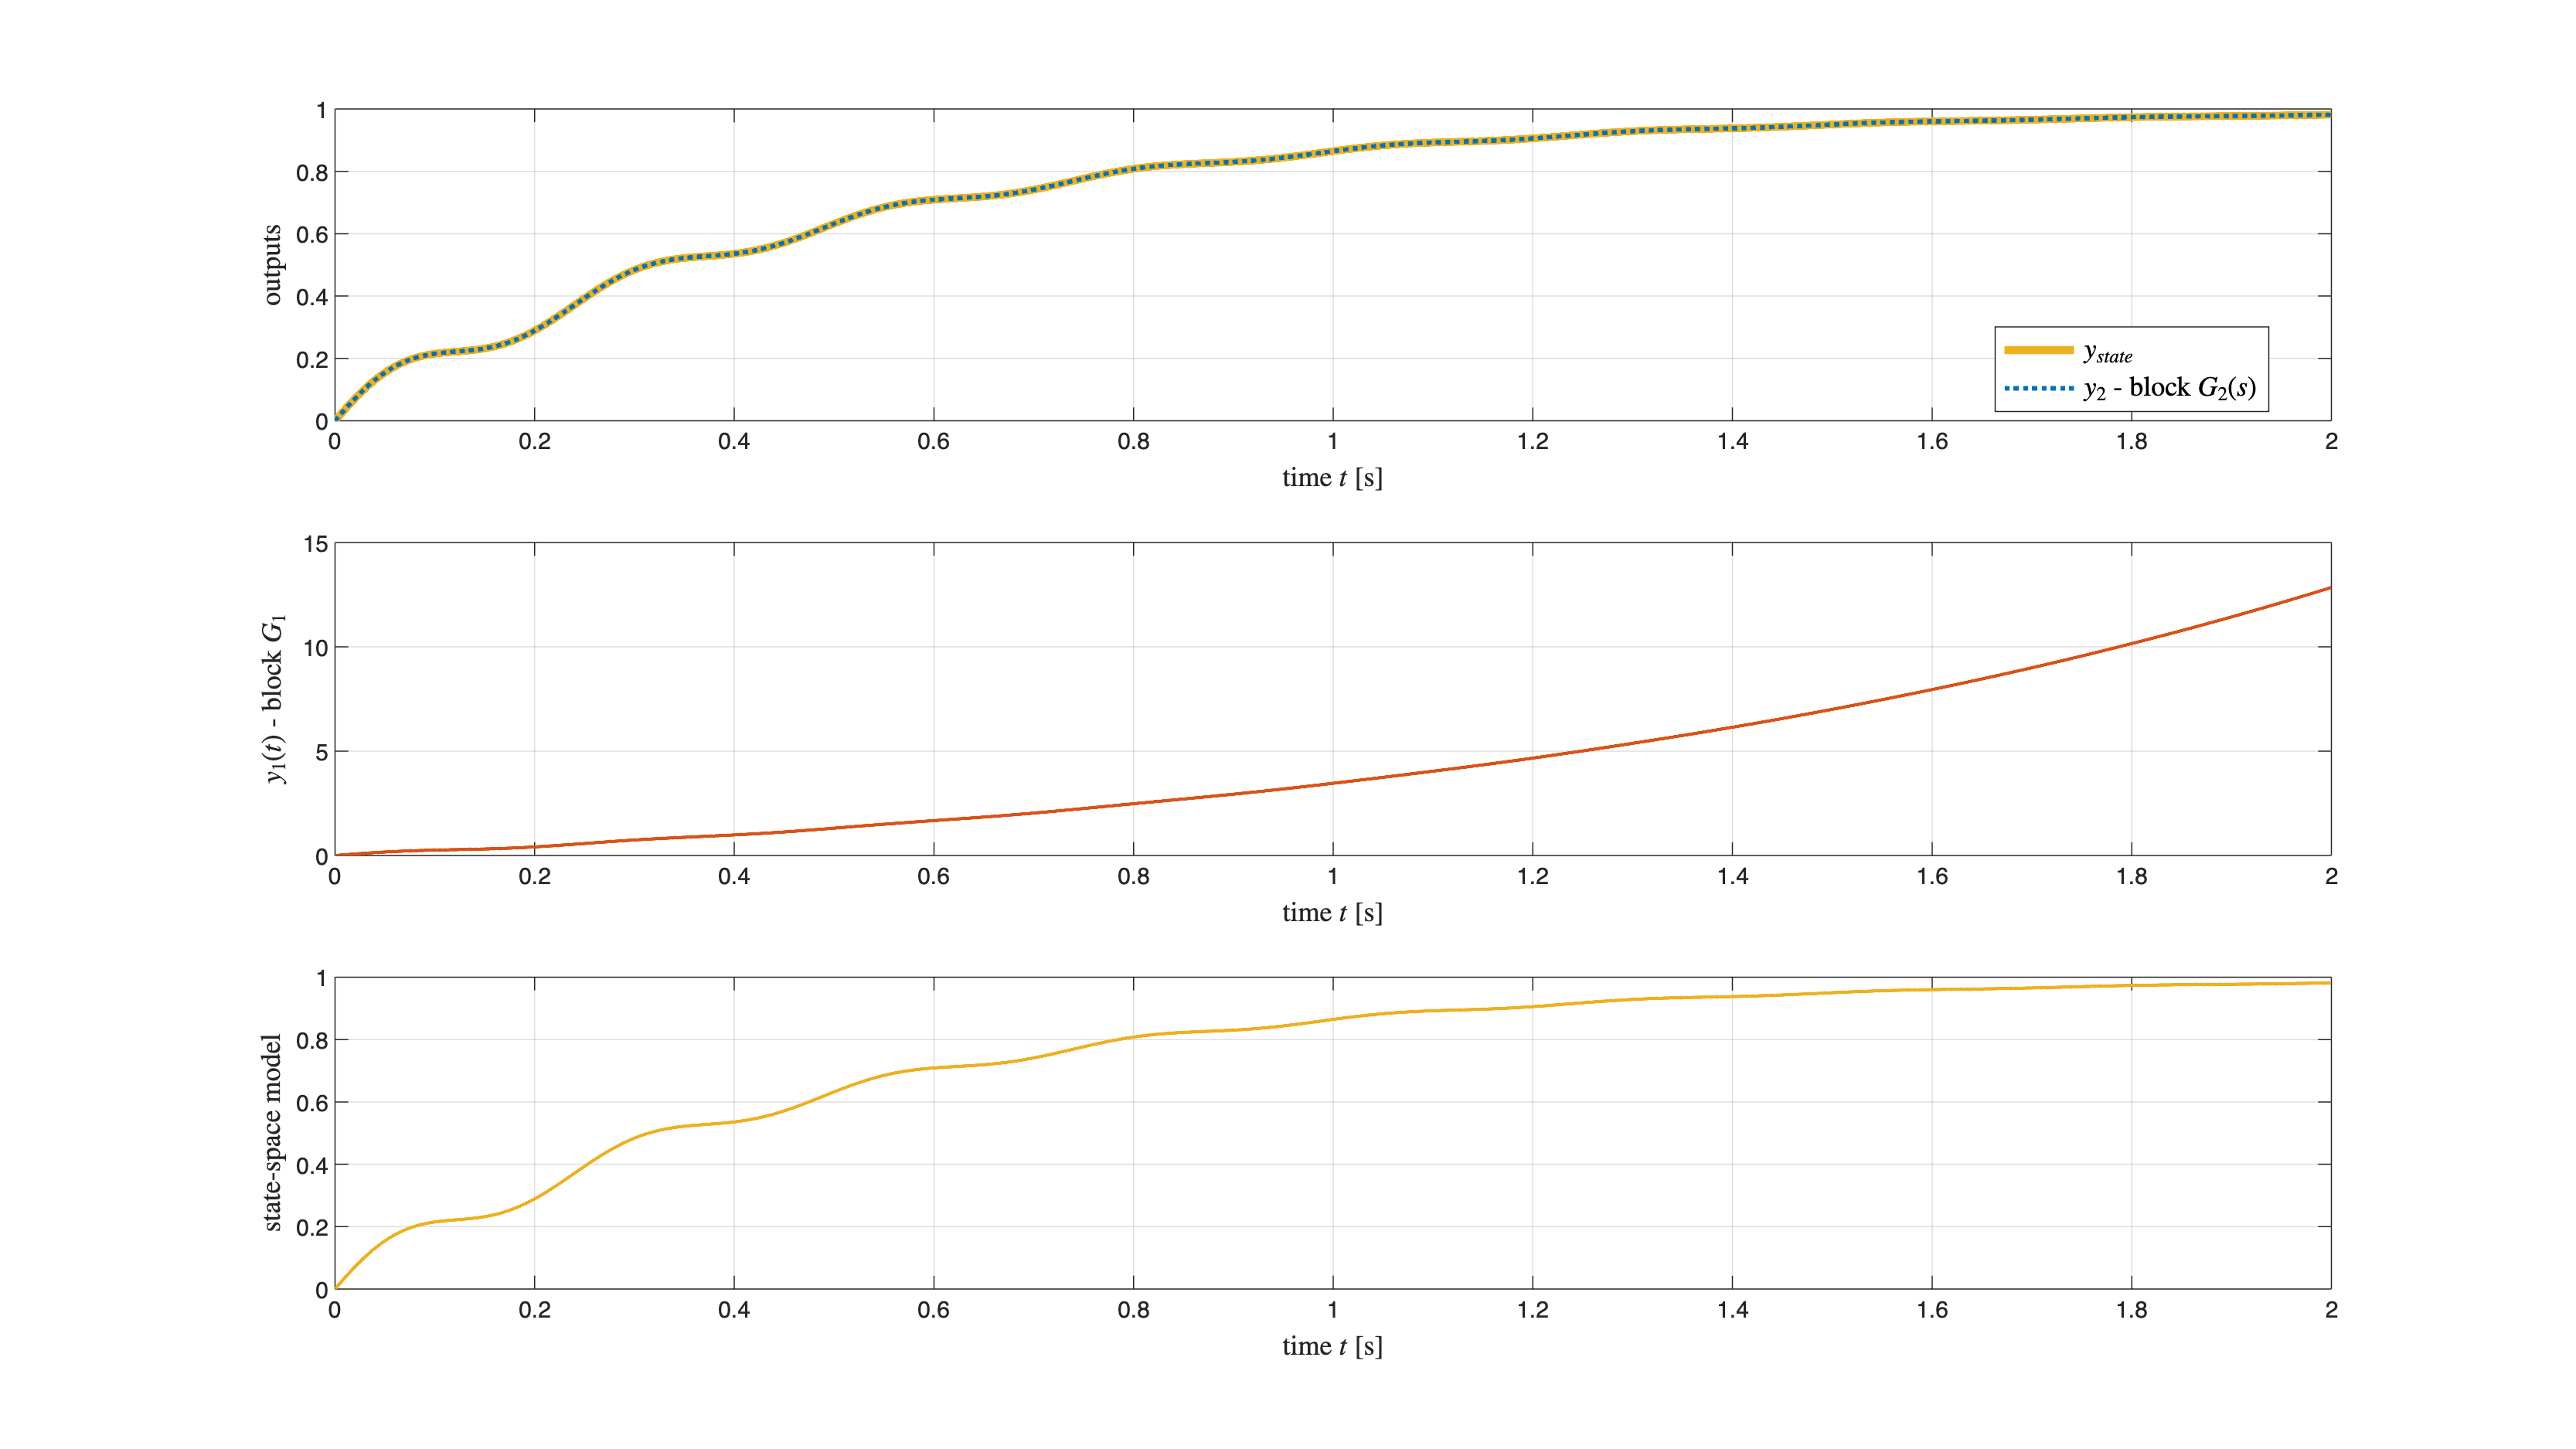

figure('Units','normalized','Position',[0.1, 0.1, 0.95, 0.95]);

ha1 = subplot(3,1,1);

plot(t_stamps, y_state, 'LineWidth', 3.5, 'Color', [0.9290 0.6940 0.1250]);
grid on; zoom on; hold on
plot(t_stamps, y2, 'LineWidth', 2.0, 'Color', [0 0.4470 0.7410], 'LineStyle', ':'); % output of the block G1

xlabel('time $t$ [s]', 'FontSize', 12, 'Interpreter','latex'); % labels on the plot axes
ylabel('outputs', 'FontSize', 12, 'Interpreter','latex'); 
legend('$y_{state}$', '$y_{2}$ - block $G_{2}(s)$',  ...
        'Interpreter', 'latex', 'FontSize', 12, 'Location', 'best' );% adding a legend


ha2 = subplot(3,1,2);
plot(t_stamps, y1, 'LineWidth', 1.5, 'Color', [0.8500 0.3250 0.0980]); % output of the block G1
grid on; zoom on;
xlabel('time $t$ [s]', 'FontSize', 12, 'Interpreter','latex'); % labels on the plot axes
ylabel('$y_1(t)$ - block $G_1$', 'FontSize', 12, 'Interpreter','latex'); 

ha3 = subplot(3,1,3);
plot(t_stamps, y_state, 'LineWidth', 1.5, 'Color', [0.9290 0.6940 0.1250]); % output of the state-space model
grid on; zoom on;
xlabel('time $t$ [s]', 'FontSize', 12, 'Interpreter','latex'); % labels on the plot axes
ylabel('state-space model', 'FontSize', 12, 'Interpreter','latex'); 
linkaxes([ha1, ha2, ha3],'x')

#### Remark 

Note: as expected, the intermediate output $y_1(t)$ diverges, whereas the overall output (i.e., the second block's output $y_2(t)$ , equal to the state space model output  $y_{state}(t)$) does not diverge.

## Example 2: Parallel Interconnections

### The Hidden Internal Dynamics is Unstable

Consider the system described in the following block diagram:

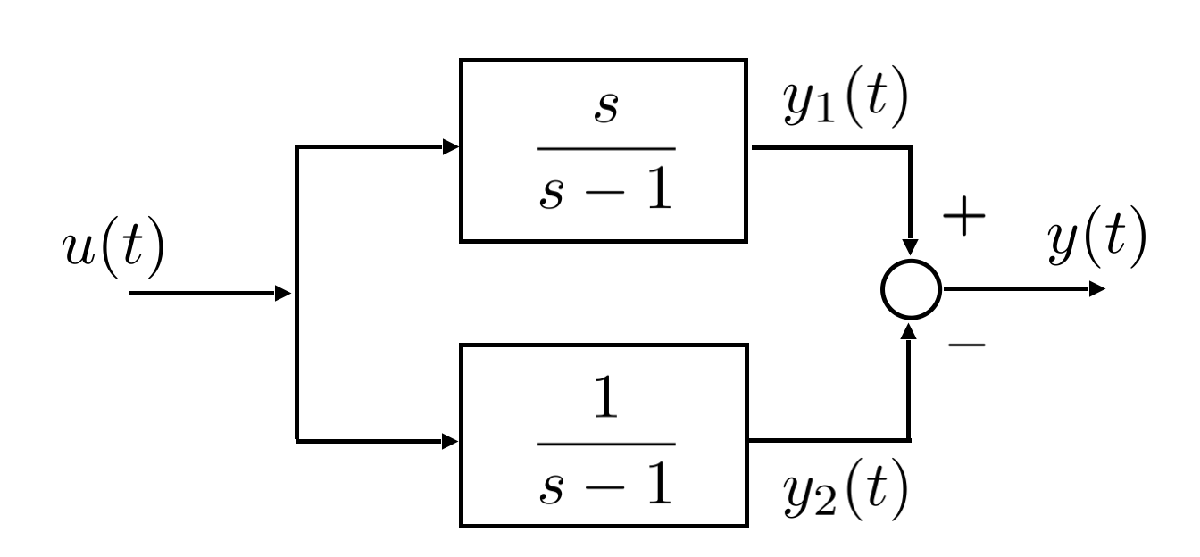


$$G_1(s) = \frac{s}{s-1} \quad G_2(s) =\frac{1}{s-1} \qquad G_{tot}(s) = G_1(s) \cdot G_2(s) = 1$$


clear
s = tf('s'); % the transfer function building helper

G1s_parallel = s/(s-1); G2s_parallel = 1/(s-1);
G_tot_parallel = minreal(G1s_parallel - G2s_parallel) % let's force the pole/zero simplification -- see 'doc minreal'


G_tot_parallel =
 
  1
 
Static gain.
Model Properties


The overall model using state variables is


$$\left\{ \begin{array}{rcl}
\left[ \begin{array}{c} \dot{x}_1(t) \\ \dot{x}_2(t) \end{array} \right] &=& 
\left[ \begin{array}{cc} 1 & 0 \\ 0 & 1 \end{array} \right] \, 
 \left[ \begin{array}{c} x_1(t) \\ x_2(t) \end{array} \right] + 
\left[ \begin{array}{c} 1 \\ 1 \end{array} \right] u(t)\\
y(t) &=& \left[ \begin{array}{cc} 1 & -1 \end{array} \right] \, 
 \left[ \begin{array}{c} x_1(t) \\ x_2(t) \end{array} \right] + \left[ \begin{array}{c} 1 \end{array} \right] u(t)
\end{array} \right.$$


Let's define it in MATLAB

A = [1 , 0; 0, 1]; B = [1; 1]; C = [1 , -1]; D = 1;
sys_TOT_parallel = ss(A, B, C, D);

#### The Input and the Simulation Settings

Now, let's assign the simulation settings and the system input:


% -----------------------------------------------------------------------
Tstop = 8; % [s] - the simulation starts at the time instant 0 and ends at thee time instant Tstop

% let's define the input time function
% let's generate NT samples for the input signal
NT = 1e4;
t = linspace(0, Tstop, NT);

% the input values
U = 2 + 1.75 .* exp(-1.4.*t) .* cos(2*pi*4.*t); 


#### The Simulation

% --- simulation of G1 ONLY ---
[yG1p, ~, xG1p] = lsim(G1s_parallel, U, t);

% --- simulation of G2 ONLY ---
[yG2p, ~, xG2p] = lsim(G2s_parallel, U, t); % <-- PAY ATTENTION: the output of G1(s) is the input for G2(s)

% --- simulation of the full system ---
[yOutp, ~, xOutp] = lsim(sys_TOT_parallel, U, t);
% let us run the model and retrieve the results 


y1 = yG1p; % output of the block G1
y2 = yG2p; % output of the block G2
y_tot = y1-y2;
y_state = yOutp; % output of the state space model

t_stamps = t; 
% time instants corresponding to the solution samples 

#### The Simulation Results

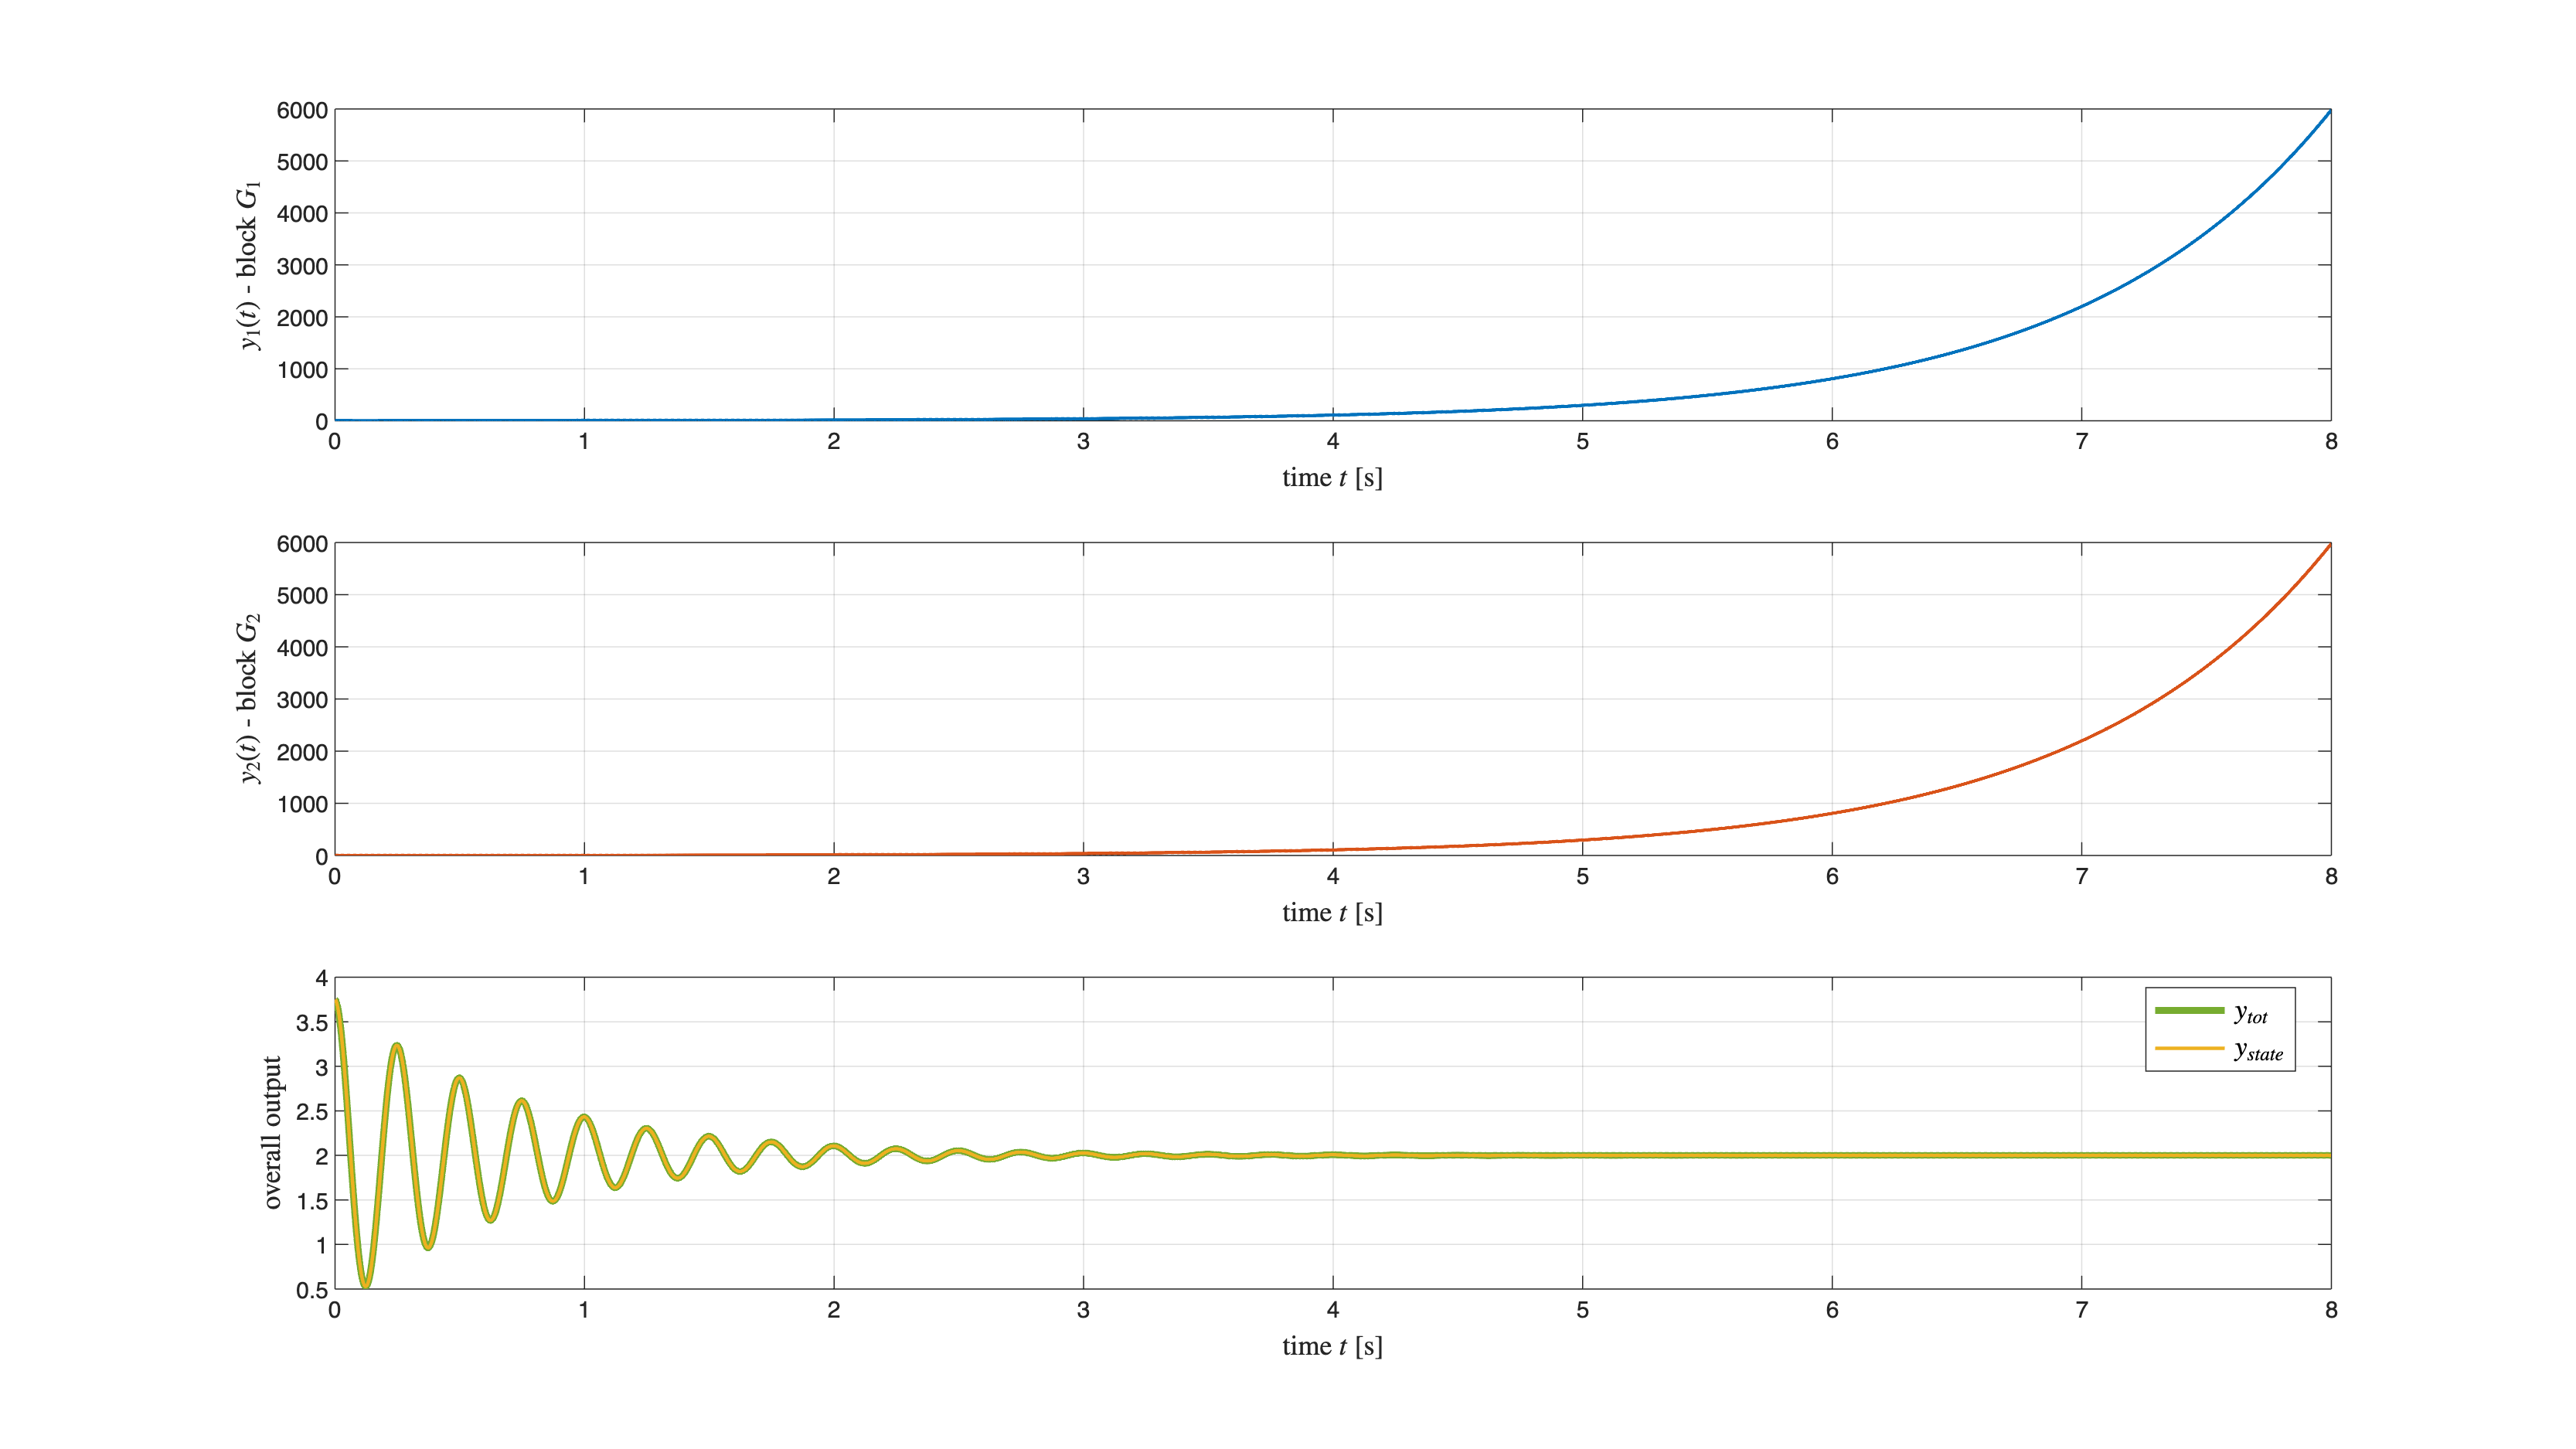

figure('Units','normalized','Position',[0.1, 0.1, 0.95, 0.95]);

ha1 = subplot(3,1,1);
plot(t_stamps, y1, 'LineWidth', 1.5, 'Color', [0 0.4470 0.7410]); % output of the block G1
grid on; zoom on; hold on
xlabel('time $t$ [s]', 'FontSize', 12, 'Interpreter','latex'); % labels on the plot axes
ylabel('$y_1(t)$ - block $G_1$', 'FontSize', 12, 'Interpreter','latex'); 

ha2 = subplot(3,1,2);
plot(t_stamps, y2, 'LineWidth', 1.5, 'Color', [0.8500 0.3250 0.0980]); % output of the block G2
grid on; zoom on;
xlabel('time $t$ [s]', 'FontSize', 12, 'Interpreter','latex'); % labels on the plot axes
ylabel('$y_2(t)$ - block $G_2$', 'FontSize', 12, 'Interpreter','latex'); 

ha3 = subplot(3,1,3);
plot(t_stamps, y_tot, 'LineWidth', 3.0, 'Color', [0.4660 0.6740 0.1880]); % overall output 
grid on; zoom on;
xlabel('time $t$ [s]', 'FontSize', 12, 'Interpreter','latex'); % labels on the plot axes
ylabel('overall output', 'FontSize', 12, 'Interpreter','latex'); 
hold on
plot(t_stamps, y_state, 'LineWidth', 1.5, 'Color', [0.9290 0.6940 0.1250]); % output of the state-space model
grid on; zoom on;
xlabel('time $t$ [s]', 'FontSize', 12, 'Interpreter','latex'); % labels on the plot axes
legend('$y_{tot}$', '$y_{state}$',...
        'Interpreter', 'latex', 'FontSize', 12, 'Location', 'best' );% adding a legend
linkaxes([ha1, ha2, ha3],'x')

#### Remark 

Note: as expected, the intermediate outputs $y_1(t)$ and $y_2(t)$ diverge, whereas the overall output (i.e., the overall output $y_{tot}(t)$ , equal to the state space model output  $y_{state}(t)$) does not diverge.